# Random graph simulation for various values of alpha

Clear Workspace

clear

Define parameters, initiate random number generator

gSize = 100;
trials = 100;
alpha = [0.2 0.3 0.5 0.7 1 1.2 1.5 2 3 5 7 10 20 50 70 100]

alpha =     0.2000    0.3000    0.5000    0.7000    1.0000    1.2000    1.5000    2.0000    3.0000    5.0000    7.0000   10.0000   20.0000   50.0000   70.0000  100.0000


rng shuffle;


Initiate matrices, setup tiled layout

A = zeros(gSize);      % initiate adjacency matrix
e_norm = zeros(gSize, trials);     % inititate eigenvalue matrix


### For all values of alpha 

for k = 1:length(alpha)
    fprintf("alpha = %d\n",alpha(k))
    for i = 1:trials

Create adjacency matrix

        r = rand(gSize) < alpha(k)/gSize;
        A = triu(r,1);
        A = A + A';

Calculate  eigenvalues

        e_norm(:,i) = eig(A)/sqrt(alpha(k));
        fprintf('%d',mod(i,10))
    end         
    e_norm;

Plot and save eigenvalue histograms

alpha = 2.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 3.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 5.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 7.000000e-01


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1.200000e+00


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 1.500000e+00


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 2


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 3


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 5


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 7


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 10


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 20


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 50


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 70


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

alpha = 100


1234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890

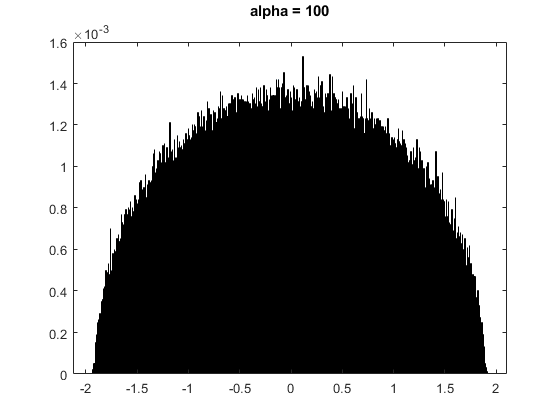

    histogram(e_norm(1:gSize-1,:),gSize,'Normalization',"probability");
    title(sprintf("alpha = %d\n",alpha(k)));
    print(strcat(strrep(string(alpha(k)),".","_"),".png"),'-dpng');
end